## Why broadband phase is not a thing, illustrated by the Hilbert transform

Many papers deal with phase relationships between signals collected at different time points or at different locations, and/or different frequencies (cross-frequency coupling). Surprisingly many of these analyses are unlikely to have worked because they measured phase from broadband signals. This walkthrough uses the hilbert transform to show why broad band phase is not a thing and how not taking this seriously yield spurious results that will never ever replicate. 

We start by making a discrete time vector, at which the signal will be sampled. 

clear
time = 0.001:0.001:4; % 4 seconds of discrete time, sampled at 1000 Hz

now, we make a time series of Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data. the middle two seconds have a 10 Hz test signal. 

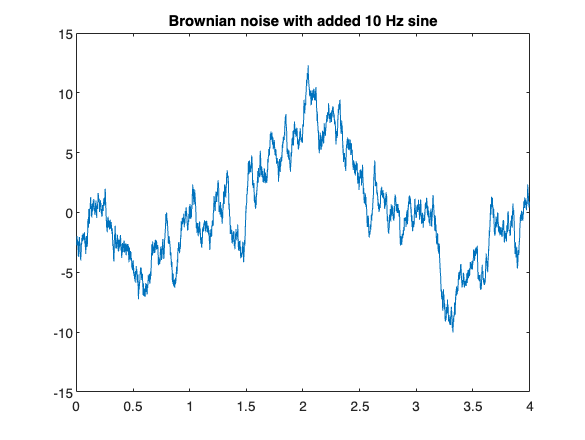

rng(08913) % set random number generator, for repproducibility
temp1 = rand(size(time))-.5; % zero-center the white noise, because we use cumulative sum later
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise
brownsig = detrend(brownsig);
figure
addsig = sin(2*time*pi*10); % hide some 10 Hz in there to make it interesting
%first and last second of test signal are zero
addsig([1:1000 3001:4000]) = 0;
data = brownsig + addsig;
plot(time, data),title('Brownian noise with added 10 Hz sine') 

Next filter the signal a bit, but not enough...let us start with 5 to 13 Hz, often used in the literature, 

[alow,blow] = butter(3, 13/500);   % 13 Hz lowpass when sampled at 1000 Hz

siglow1 = filtfilt(alow, blow, data);

[ahigh,bhigh] = butter(2, 5/500, 'high')% 5 Hz highpass (2nd order) when sampled at 1000 Hz

ahigh =     0.9780   -1.9561    0.9780


bhigh =     1.0000   -1.9556    0.9565



sighighlow1 = filtfilt(ahigh, bhigh, siglow1);


Now we apply the Hilbert transform. It estimates the local phase time-point by time point and creates a version that is shifted by 90 degrees. it is often used in CFC studies. For example 4 Hz in Canolty et al. *Science* 2016

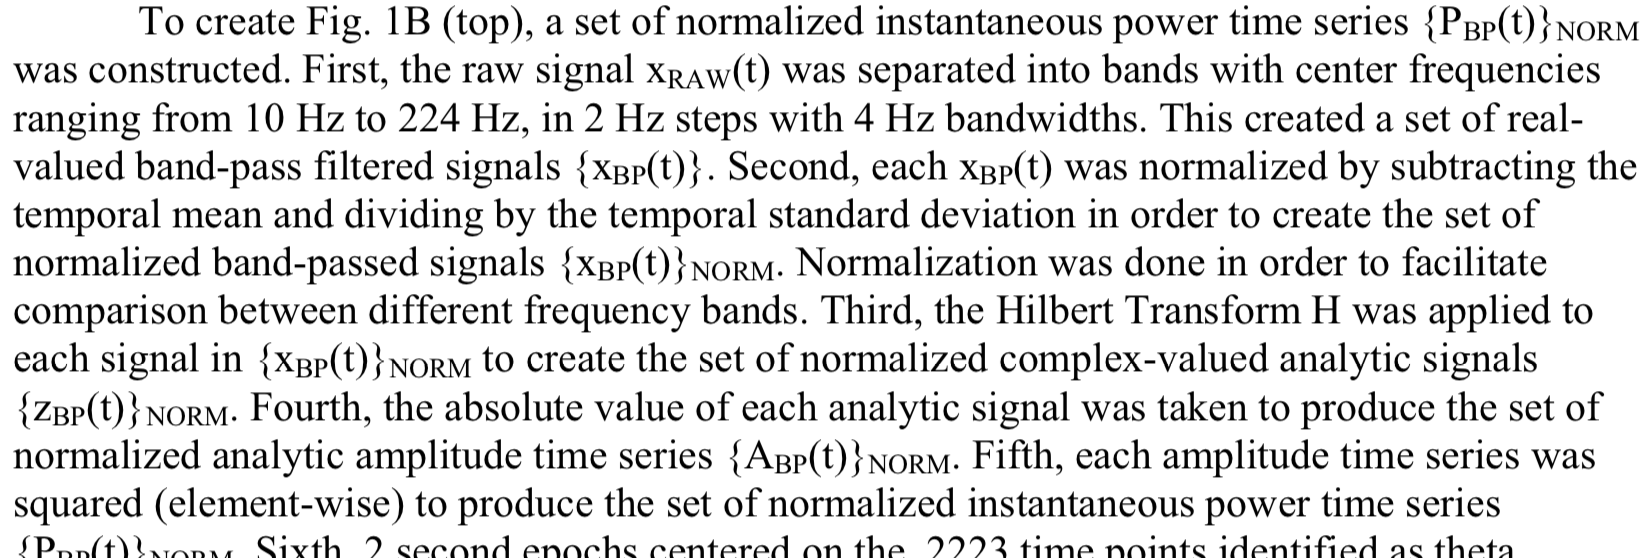

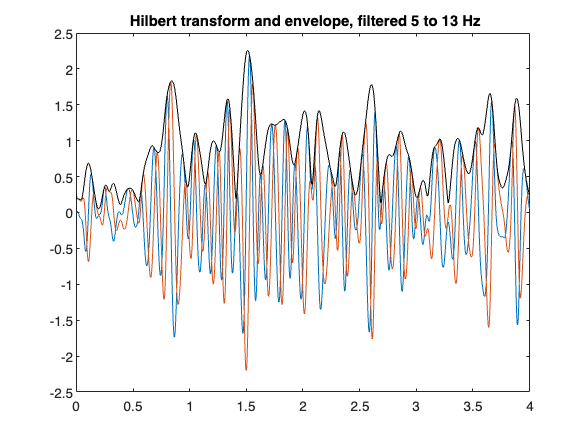

test1 = hilbert(sighighlow1);

figure, 
plot(time, sighighlow1)
title(' Hilbert transform and envelope, filtered 5 to 13 Hz')
hold on

plot(time, imag(test1))
plot(time, abs(test1), 'k'), hold off

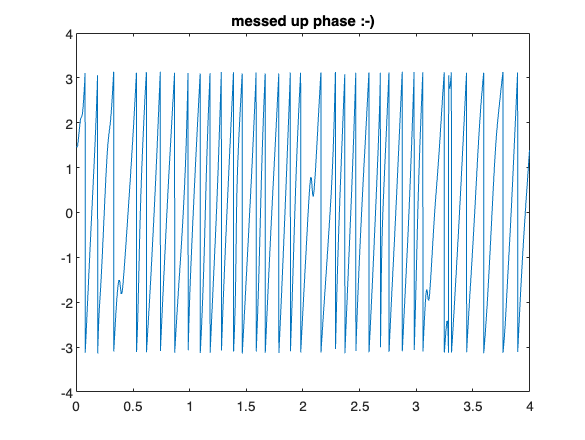


figure, plot(time, angle(test1)), title('messed up phase :-)')

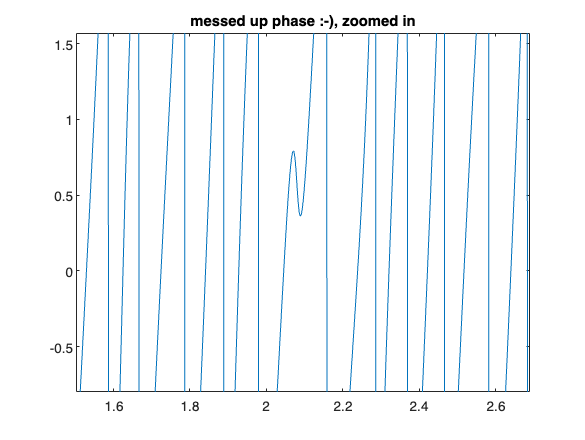


figure, plot(time, angle(test1)), title('messed up phase :-), zoomed in')
xlim([1.503 2.689])
ylim([-0.80 1.57])

now do it again properly, with better band pass, still accoetable but not optimal 


[alow,blow] = butter(6, 10.5/500);   % 10.5 Hz lowpass when sampled at 1000 Hz

siglow = filtfilt(alow, blow, data);

[ahigh,bhigh] = butter(4, 9.5/500, 'high')% 9.5 Hz highpass (4th order) when sampled at 1000 Hz

ahigh =     0.9250   -3.6998    5.5498   -3.6998    0.9250


bhigh =     1.0000   -3.8440    5.5441   -3.5557    0.8556


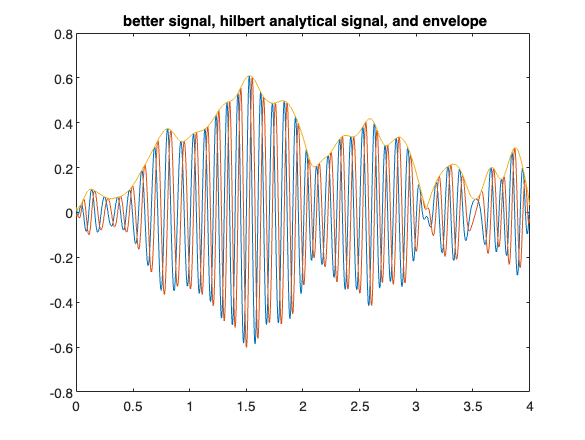


sighighlow = filtfilt(ahigh, bhigh, siglow);

figure(3)

plot(time, sighighlow), title(' better signal, hilbert analytical signal, and envelope')

test = hilbert(sighighlow);

hold on, plot(time, imag(test))

plot(time, abs(test)), hold off

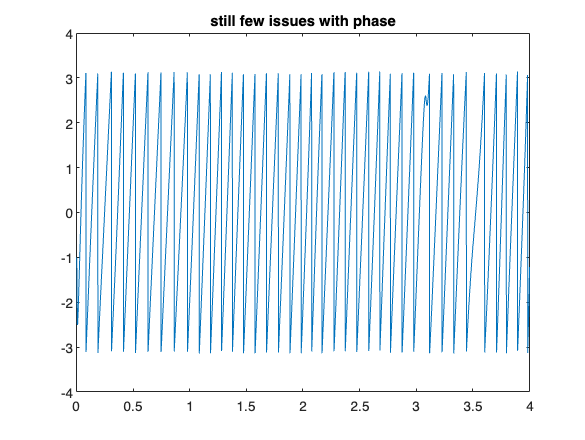


figure(4)

plot(time, angle(test)), title('still few issues with phase')

now do it again, with even more narrow band pass 


[alow,blow] = butter(6, 10.2/500);   % lowpass when sampled at 1000 Hz

siglow = filtfilt(alow, blow, data);

[ahigh,bhigh] = butter(6, 9.8/500, 'high')%  highpass when sampled at 1000 Hz

ahigh =     0.8878   -5.3270   13.3174  -17.7565   13.3174   -5.3270    0.8878


bhigh =     1.0000   -5.7621   13.8386  -17.7314   12.7836   -4.9169    0.7882


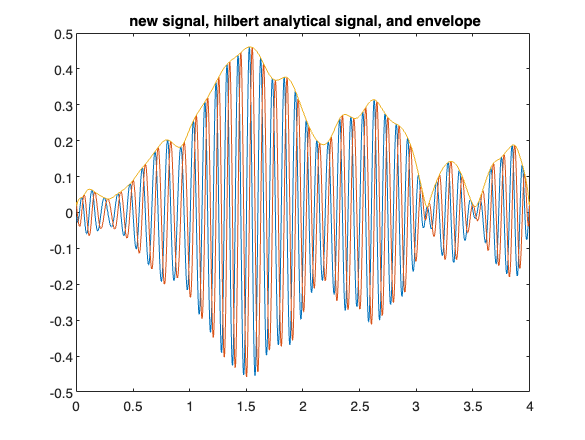


sighighlow = filtfilt(ahigh, bhigh, siglow);

figure(3)

plot(time, sighighlow), title(' new signal, hilbert analytical signal, and envelope')

test = hilbert(sighighlow);

hold on, plot(time, imag(test))

plot(time, abs(test)), hold off

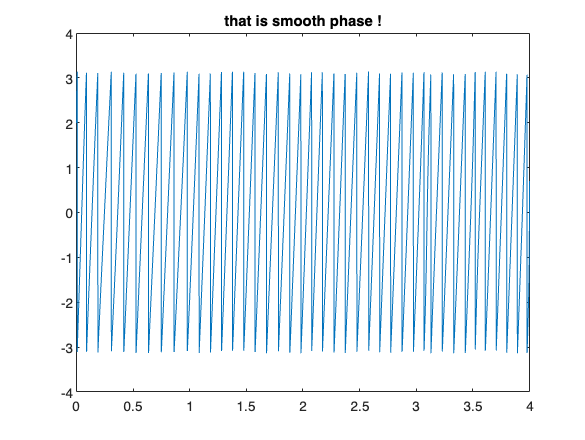


figure(4)

plot(time, angle(test)), title('that is smooth phase !')

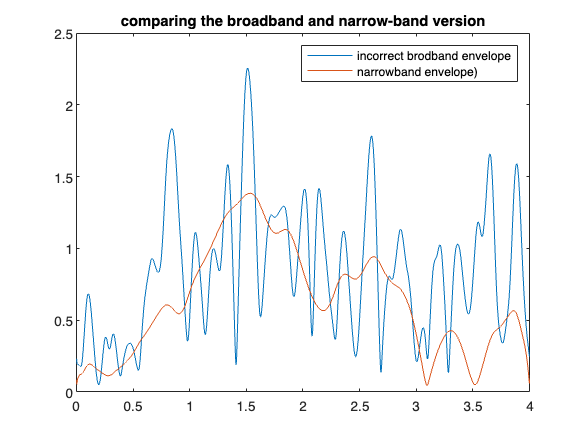

plot(time, abs(test1)), hold on 
plot(time, abs(test).*3) % scale to counter filter attenuation
title("comparing the broadband and narrow-band version")
legend('incorrect brodband envelope', 'narrowband envelope)')


disp('correlations between the representations of the same signal, with correct vs incorrect application:')

correlations between the representations of the same signal, with correct vs incorrect application:


disp('correlation between the real parts if acceptable-ish, this is why people are not worried :-) ')

correlation between the real parts if acceptable-ish, this is why people are not worried :-) 


corr(real(test1)', real(test)')

ans = 0.7271


disp('correlation between the phase angles across time points')

correlation between the phase angles across time points


corr(angle(test1)', angle(test)')

ans = 0.4422


disp('correlation between the time-varying amplitude envelopes across time')

correlation between the time-varying amplitude envelopes across time


corr(abs(test1)', abs(test)')

ans = 0.4834